
clear all;
close all;

load('E:\Data\2024-12-30\Abs-1248\Aver173.mat');


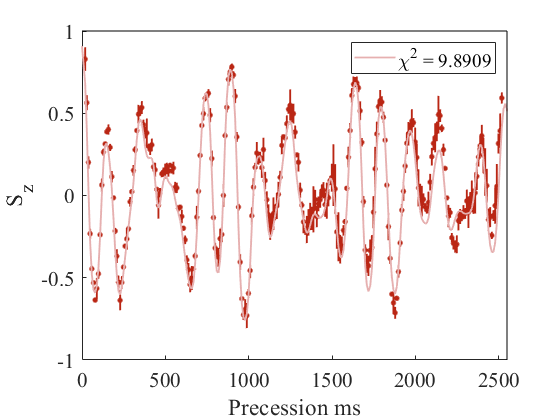


xmin = 0;
xmax = 2550;
sample = 200;

%signal = (s1-s2)./(s1+s2);
signal = phase_mean;
w = 1./phase_std.^2;

colors = npg(100);
F=5/2;
sigmax = spinOp(F,'x');
sigmay = spinOp(F,'y');
sigmaz = spinOp(F,'z');

initial = zeros(2*F+1,1);
initial(1) = 1;

timestep = 10;
timeend = 2550;
timelist = [0,[0:timestep:timeend]+5.5+13.4];

%% 输入变量
tensor_c = 0.01068;   % tensor 中心值, 2pi*kHz
tensor_s = 0.00040;   % tensor 分布, 2pi*kHz
tensor = tensor_c + tensor_s*randn(sample,1);
By = 2*pi*2.5*1/0.115/0.72607/5/1000*1;   % omega量纲, 2pi*kHz, 对应ms
BTR = By/tensor_c;

Delta = 1.42;   % 以Gamma为单位，+1/2与+7/2之间失谐

theta1 = 0.000;
theta2 = -0.000;

pop_state1 = 0;
pop_state2 = 0;

for n = 1:sample
    ham = By*(sigmay-theta1*sigmaz)/sqrt(1+theta1^2) + ...
        tensor(n)*(sigmaz^2+theta2*sigmay^2)/sqrt(1+theta2^2);   % omega量纲
    for k = 1:length(timelist)
        precess_state1(:,k) = ham_evolve(ham,initial,timelist(k));
        temp = ham_evolve(ham,initial,timelist(k)+13.4+4);
        temp = ham_evolve(sigmax+sigmax^2,temp,pi);
        precess_state2(:,k) = ham_evolve(ham,temp,4);
    end
    pop_state1 = pop_state1 + abs(precess_state1).^2;
    pop_state2 = pop_state2 + abs(precess_state2).^2;
end

pop_state1 = pop_state1/sample;
pop_state2 = pop_state2/sample;

detection_p = [1 (5/7)/sqrt((3/6*Delta)^2+1) (10/21)/sqrt((5/6*Delta)^2+1) ...
    (2/7)/sqrt((6/6*Delta)^2+1) (1/7)/sqrt((6/6*Delta)^2+1) (1/21)/sqrt((5/6*Delta)^2+1)];
state1 = detection_p*pop_state1;
state2 = detection_p*pop_state2;

sz(:) = (state1(1,:)-state2(1,:))./(state1(1,:)+state2(1,:));

t_signal = [0:10:2500]+5.5+13.4;
chi_square = 0;
for k = 1:length(signal)
    % precess_state1_signal(:,k) = ham_evolve(ham,initial,t_signal(k));
    % temp = ham_evolve(ham,initial,t_signal(k)+13.4+4);
    % temp = ham_evolve(sigmax+sigmax^2,temp,pi);
    % precess_state2_signal(:,k) = ham_evolve(ham,temp,4);
    % pop_state1_signal(:,k) = abs(precess_state1_signal(:,k)).^2;
    % pop_state2_signal(:,k) = abs(precess_state2_signal(:,k)).^2;
    % sz_signal(k) = 0.75*(pop_state1_signal(1,k)-pop_state2_signal(1,k))./(pop_state1_signal(1,k)+pop_state2_signal(1,k));
    temp1(k) = (signal(k)-sz(k+1))^2;
    chi_square = chi_square + w(k)*temp1(k);
end

chi_square = chi_square/(length(signal)-1);

f1 = figure; hold on;
e1 = errorbar(t_signal,signal,phase_std/sqrt(3-1),...
    '.','MarkerSize',12,'LineWidth',1.4,'CapSize',0,'Color',[0.73 0.15 0.08]);

plot(timelist,sz,'-','LineWidth',1.4,'Color',[0.9 0.69 0.69]);
ylim([-1 1]);
xlim([xmin xmax]);
xlabel('Precession ms');
ylabel('S_z');

set(gca,'FontName','times new roman','FontSize',16);

plot([xmin,xmax],[1,1],'Color','k');
plot([xmax,xmax],[-1,1],'Color','k');

legend('',['\chi^2 = ',num2str(chi_square)],'','');

set(f1,'Visible','on');


%save('D:\MATLAB_Git\MATLAB-atomic-calculation\Comag_Pub\Fig4\tensor_simulation.mat');

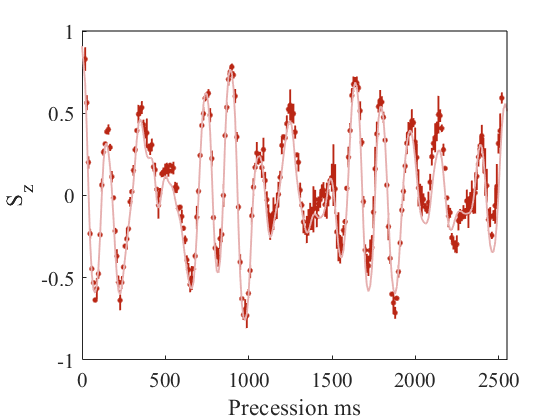

%saveas(f1,'D:\MATLAB_Git\MATLAB-atomic-calculation\Comag_Pub\Fig4\tensor_simulation.png');

%savefig(f1,'D:\MATLAB_Git\MATLAB-atomic-calculation\Comag_Pub\Fig4\tensor_simulation.fig');


function final = ham_evolve(ham,initial,time)
try
    final = expm(-1i*ham.*time)*initial;
catch 
    disp("Wrong Solution!!");
end
end
